## Staph testing

Data from original INDIGO paper

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'staph.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'staph_orthologs.xlsx';
trainingData = 'indigo';

summaryTable = 1×12 table
      min      median     max      range     mean       std      interactionCount    synergyCount    antagonismCount    orthologsCount    rejectNormality    pNormality
    _______    ______    ______    _____    ______    _______    ________________    ____________    _______________    ______________    _______________    __________

    -1.4045    0.7525    3.7195    5.124    0.7742    0.95902           45                5                17                1162              false          0.18318  


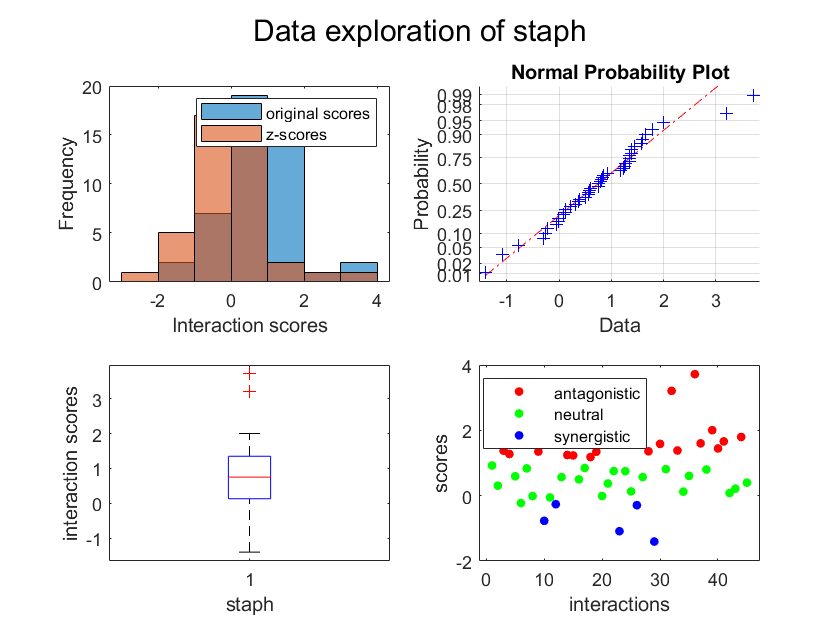

[summary,drugList] = dataExplore(testFile);

files = dataFiles();
compareFiles = [{testFile};{files.indigoData}];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    saureus_data score    orig_ecoli score
    ______    ______    __________________    ________________

    "CEF"     "CHL"           0.9235                0.769     
    "CEF"     "CLA"           0.3065               0.1665     
    "CEF"     "ERY"            1.378               0.0975     
    "CEF"     "GEN"           1.2775               0.2985     
    "CEF"     "NIT"           0.5925                2.886     
    "CEF"     "OXA"           -0.227               -0.329     
    "CEF"     "RIF"            0.836                1.121     
    "CEF"     "TET"          -0.0135              -0.0315     


interactionCounts = 2×2 table
                    saureus_data    orig_ecoli
                    ____________    __________

    saureus_data         0              45    
    orig_ecoli           0               0    


R_values = 2×2 table
                    saureus_data    orig_ecoli
                    ____________    __________

    saureus_data         0           0.38999  
    orig_ecoli           0                 0  


P_values = 2×2 table
                    saureus_data    orig_ecoli
                    ____________    __________

    saureus_data         0          0.0084829 
    orig_ecoli           0                  0 


indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 22.728241 seconds.
Run 2
Elapsed time is 16.603050 seconds.
Run 3
Elapsed time is 21.758032 seconds.
Run 4
Elapsed time is 16.755590 seconds.
Run 5
Elapsed time is 19.466911 seconds.


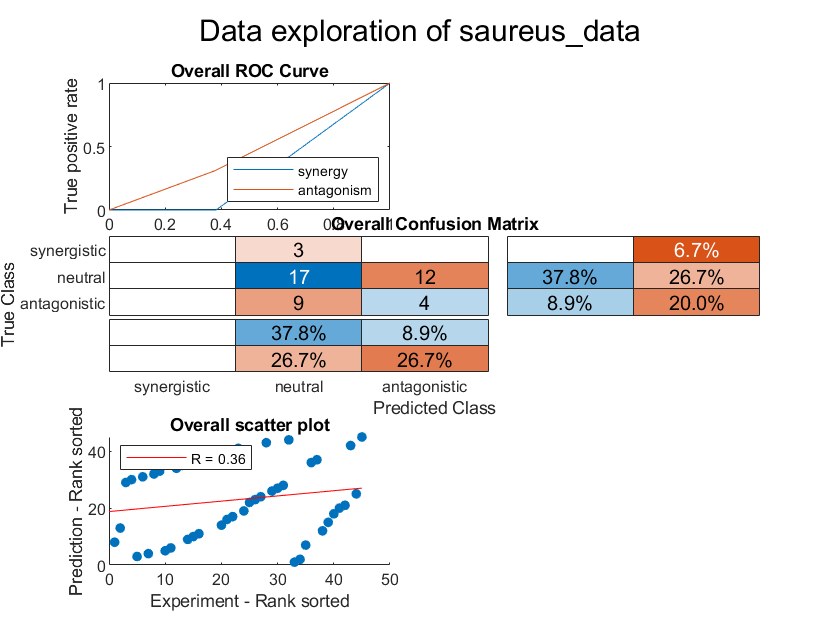

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          -0.21667    

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                       0.38
    P value                     0.25254
    Accuracy                    0.46667
    Absolute error              0.53333
    Precision (synergy)             NaN
    Recall (synergy)                NaN
    Precision (antagonism)      0.26667
    Recall (antagonism)         0.28333
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)             NaN
    AUC - ROC (antagonism)      0.45976


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      45
    R (rank)                     0.36419
    P value                     0.013915
    Accuracy                     0.46667
    Absolute error               0.53333
    Precision (synergy)              NaN
    Recall (synergy)                   0
    Precision (antagonism)          0.25
    Recall (antagonism)          0.30769
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.30952
    AUC - ROC (antagonism)       0.46635


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'saureus_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_staph_orthologs.xlsx';
trainingData = 'indigo';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 30.484099 seconds.
Run 2
Elapsed time is 19.998799 seconds.
Run 3
Elapsed time is 28.101531 seconds.
Run 4
Elapsed time is 37.483377 seconds.
Run 5
Elapsed time is 18.985290 seconds.


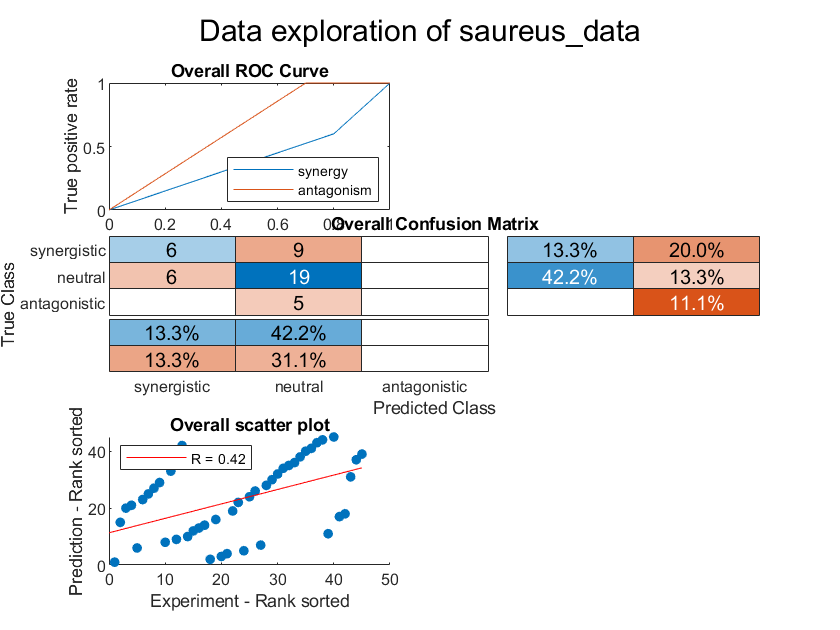

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9           0.43333

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.39667
    P value                     0.42764
    Accuracy                    0.55556
    Absolute error              0.44444
    Precision (synergy)         0.56667
    Recall (synergy)            0.43333
    Precision (antagonism)          NaN
    Recall (antagonism)             NaN
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.38857
    AUC - ROC (antagonism)          NaN


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       45
    R (rank)                      0.41749
    P value                     0.0043257
    Accuracy                      0.55556
    Absolute error                0.44444
    Precision (synergy)               0.5
    Recall (synergy)                  0.4
    Precision (antagonism)            NaN
    Recall (antagonism)                 0
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)               0.4
    AUC - ROC (antagonism)           0.65


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'saureus_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_staph_orthologs.xlsx';
trainingData = 'nature';
standardize = '';

files = dataFiles();
compareFiles = [testFile;files.natureData];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 2×4 table
    Drug 1    Drug 2    saureus_data score    ecoli_bw25113 score
    ______    ______    __________________    ___________________

    "CHL"     "NIT"            0.567               0.062737      
    "CHL"     "RIF"           1.2325               -0.35201      


sharedInteractionsPreview = 2×4 table
    Drug 1    Drug 2    saureus_data score    ecoli_iAi1 score
    ______    ______    __________________    ________________

    "CHL"     "NIT"            0.567              -0.41592    
    "CHL"     "RIF"           1.2325                0.1113    


saureus_data and stlt2 have no shared interactions

saureus_data and st14028 have no shared interactions



sharedInteractionsPreview = 2×4 table
    Drug 1    Drug 2    saureus_data score    pao1 score
    ______    ______    __________________    __________

    "CHL"     "NIT"            0.567            0.08089 
    "NIT"     "RIF"           1.6025           -0.13448 


sharedInteractionsPreview = 2×4 table
    Drug 1    Drug 2    saureus_data score    pa14 score
    ______    ______    __________________    __________

    "CHL"     "NIT"            0.567            0.11999 
    "NIT"     "RIF"           1.6025          -0.030558 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "A22"     "ATM"          -0.11682              -0.23949    
    "A22"     "BLM"          -0.18842              -0.22326    
    "A22"     "MMC"          -0.15416              0.081189    
    "A22"     "PUR"           0.10034               0.10767    
    "A22"     "PYO"           0.28322             -0.082868    
    "A22"     "RIF"          0.099699               0.17919    
    "AMK"     "AZM"           0.20244              0.039346    
    "AMK"     "BZK"           0.40112              0.082268    


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    stlt2 score
    ______    ______    ___________________    ___________

    "A22"     "MMC"           -0.15416           0.19836  
    "AMK"     "BZK"            0.40112           0.29453  
    "AMK"     "EGCG"           0.13458           0.13635  
    "AMK"     "ERI"            0.20099           0.15979  
    "AMK"     "LCX"          -0.044191          -0.36433  
    "AMK"     "PMS"            0.48777           0.31997  
    "AMK"     "PRC"            0.47286           0.19732  
    "AMK"     "PUR"           -0.42117          -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    st14028 score
    ______    ______    ___________________    _____________

    "A22"     "MMC"           -0.15416            0.046942  
    "AMK"     "BZK"            0.40112             0.28743  
    "AMK"     "EGCG"           0.13458            0.023459  
    "AMK"     "ERI"            0.20099           -0.035934  
    "AMK"     "LCX"          -0.044191            -0.42079  
    "AMK"     "PMS"            0.48777            -0.11198  
    "AMK"     "PRC"            0.47286            0.076645  
    "AMK"     "PUR"           -0.42117           -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pao1 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           0.040284 
    "A22"     "MMC"          -0.15416          -0.099203 
    "AMK"     "AZM"           0.20244            0.68877 
    "AMK"     "EGCG"          0.13458            0.14272 
    "AMK"     "ERI"           0.20099            0.28607 
    "AMK"     "MMC"           -0.2502           0.062727 
    "AMK"     "NIT"          -0.21472            0.22065 
    "AMK"     "PRC"           0.47286            0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pa14 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           -0.11745 
    "A22"     "MMC"          -0.15416            0.27324 
    "AMK"     "AZM"           0.20244            0.40503 
    "AMK"     "EGCG"          0.13458           0.083746 
    "AMK"     "ERI"           0.20099            0.20578 
    "AMK"     "MMC"           -0.2502            0.12617 
    "AMK"     "NIT"          -0.21472          -0.052538 
    "AMK"     "PRC"           0.47286             0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    stlt2 score
    ______    ______    ________________    ___________

    "A22"     "MMC"         0.081189          0.19836  
    "AMK"     "BZK"         0.082268          0.29453  
    "AMK"     "EGCG"        0.034852          0.13635  
    "AMK"     "ERI"         0.047723          0.15979  
    "AMK"     "LCX"          -0.1704         -0.36433  
    "AMK"     "PMS"         0.048965          0.31997  
    "AMK"     "PRC"         0.059603          0.19732  
    "AMK"     "PUR"         -0.26455         -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    st14028 score
    ______    ______    ________________    _____________

    "A22"     "MMC"         0.081189           0.046942  
    "AMK"     "BZK"         0.082268            0.28743  
    "AMK"     "EGCG"        0.034852           0.023459  
    "AMK"     "ERI"         0.047723          -0.035934  
    "AMK"     "LCX"          -0.1704           -0.42079  
    "AMK"     "PMS"         0.048965           -0.11198  
    "AMK"     "PRC"         0.059603           0.076645  
    "AMK"     "PUR"         -0.26455          -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pao1 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         0.040284 
    "A22"     "MMC"         0.081189        -0.099203 
    "AMK"     "AZM"         0.039346          0.68877 
    "AMK"     "EGCG"        0.034852          0.14272 
    "AMK"     "ERI"         0.047723          0.28607 
    "AMK"     "MMC"         -0.11537         0.062727 
    "AMK"     "NIT"         -0.30784          0.22065 
    "AMK"     "PRC"         0.059603          0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pa14 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         -0.11745 
    "A22"     "MMC"         0.081189          0.27324 
    "AMK"     "AZM"         0.039346          0.40503 
    "AMK"     "EGCG"        0.034852         0.083746 
    "AMK"     "ERI"         0.047723          0.20578 
    "AMK"     "MMC"         -0.11537          0.12617 
    "AMK"     "NIT"         -0.30784        -0.052538 
    "AMK"     "PRC"         0.059603           0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    st14028 score
    ______    ______    ___________    _____________

    "A22"     "GEN"       0.12582          0.16781  
    "A22"     "MMC"       0.19836         0.046942  
    "AMK"     "ATM"      -0.30991         -0.14214  
    "AMK"     "BZK"       0.29453          0.28743  
    "AMK"     "CEC"      -0.11493         -0.16492  
    "AMK"     "EGCG"      0.13635         0.023459  
    "AMK"     "ERI"       0.15979        -0.035934  
    "AMK"     "LCX"      -0.36433         -0.42079  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pao1 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836     -0.099203 
    "AMK"     "ATM"       -0.30991      -0.32109 
    "AMK"     "EGCG"       0.13635       0.14272 
    "AMK"     "ERI"        0.15979       0.28607 
    "AMK"     "PRC"        0.19732       0.19014 
    "AMK"     "TOB"       -0.33487      -0.13132 
    "AMX"     "AMK"        -0.1155      -0.19518 
    "AMX"     "CIP"      -0.047861      0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pa14 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836       0.27324 
    "AMK"     "ATM"       -0.30991      -0.50344 
    "AMK"     "EGCG"       0.13635      0.083746 
    "AMK"     "ERI"        0.15979       0.20578 
    "AMK"     "PRC"        0.19732        0.1142 
    "AMK"     "TOB"       -0.33487      -0.12544 
    "AMX"     "AMK"        -0.1155       -0.2228 
    "AMX"     "CIP"      -0.047861        0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pao1 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942      -0.099203 
    "AMK"     "ATM"        -0.14214       -0.32109 
    "AMK"     "EGCG"       0.023459        0.14272 
    "AMK"     "ERI"       -0.035934        0.28607 
    "AMK"     "PRC"        0.076645        0.19014 
    "AMK"     "TOB"        -0.10058       -0.13132 
    "AMX"     "AMK"          -0.145       -0.19518 
    "AMX"     "CIP"         0.22995       0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pa14 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942        0.27324 
    "AMK"     "ATM"        -0.14214       -0.50344 
    "AMK"     "EGCG"       0.023459       0.083746 
    "AMK"     "ERI"       -0.035934        0.20578 
    "AMK"     "PRC"        0.076645         0.1142 
    "AMK"     "TOB"        -0.10058       -0.12544 
    "AMX"     "AMK"          -0.145        -0.2228 
    "AMX"     "CIP"         0.22995         0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    pao1 score    pa14 score
    ______    ______    __________    __________

    "AMK"     "A22"      0.030386      -0.15949 
    "AMX"     "A22"      0.047543      -0.13341 
    "CHL"     "A22"      0.046395       0.10396 
    "DOX"     "A22"      -0.03145        0.1363 
    "FOF"     "A22"      0.049735      -0.59174 
    "NIT"     "A22"      0.033376       0.14544 
    "PRC"     "A22"      0.042237       0.20696 
    "AMX"     "AMK"      -0.19518       -0.2228 


interactionCounts = 7×7 table
                     saureus_data    ecoli_bw25113    ecoli_iAi1    stlt2    st14028    pao1    pa14
                     ____________    _____________    __________    _____    _______    ____    ____

    saureus_data          0                2               2           0         0        2       2 
    ecoli_bw25113         0                0             316         148       148       72      72 
    ecoli_iAi1            0                0               0         148       148       72      72 
    stlt2                 0                0               0           0       248       53      53 
    st14028               0             

R_values = 7×7 table
                     saureus_data    ecoli_bw25113    ecoli_iAi1    stlt2     st14028      pao1       pa14  
                     ____________    _____________    __________    ______    _______    ________    _______

    saureus_data          0               -1                 1           0          0          -1         -1
    ecoli_bw25113         0                0           0.64896       0.745    0.67384     0.24449    0.39303
    ecoli_iAi1            0                0                 0      0.6407    0.64464    0.081516     0.3926
    stlt2                 0                0                 0           0    0.61859     0.56628    0.52959
    st1402

P_values = 7×7 table
                     saureus_data    ecoli_bw25113    ecoli_iAi1    stlt2    st14028       pao1          pa14   
                     ____________    _____________    __________    _____    _______    __________    __________

    saureus_data          0                1              1           0         0                1             1
    ecoli_bw25113         0                0              0           0         0         0.038725    0.00063738
    ecoli_iAi1            0                0              0           0         0           0.4952    0.00064705
    stlt2                 0                0              0           0         0       1.4236e-05     5.91

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 111.614709 seconds.
Run 2
Elapsed time is 80.853741 seconds.
Run 3
Elapsed time is 108.845219 seconds.
Run 4
Elapsed time is 126.683157 seconds.
Run 5
Elapsed time is 102.830678 seconds.


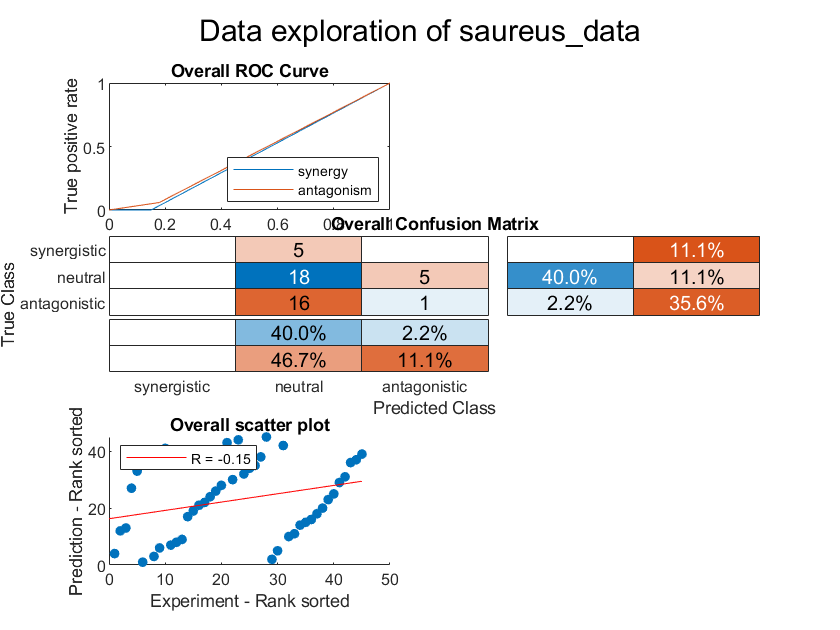

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          -0.13333    

averagesTable = 12×1 table
                                 Value  
                                ________

    Interactions                       9
    R (rank)                       -0.13
    P value                      0.35624
    Accuracy                     0.42222
    Absolute error               0.57778
    Precision (synergy)              NaN
    Recall (synergy)                 NaN
    Precision (antagonism)           NaN
    Recall (antagonism)         0.066667
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)              NaN
    AUC - ROC (antagonism)          0.45


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      45
    R (rank)                    -0.15025
    P value                      0.32456
    Accuracy                     0.42222
    Absolute error               0.57778
    Precision (synergy)              NaN
    Recall (synergy)                   0
    Precision (antagonism)       0.16667
    Recall (antagonism)         0.058824
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)            0.425
    AUC - ROC (antagonism)       0.44013


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'saureus_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_staph_orthologs.xlsx';
trainingData = 'nature';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 86.150544 seconds.
Run 2
Elapsed time is 118.648393 seconds.
Run 3
Elapsed time is 91.015861 seconds.
Run 4
Elapsed time is 90.400899 seconds.
Run 5
Elapsed time is 84.658219 seconds.


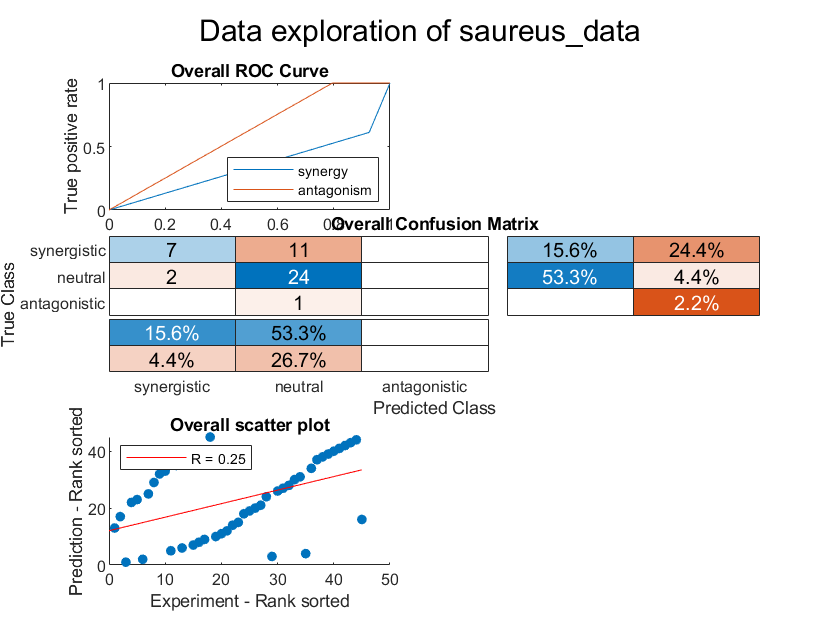

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9                0   

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.23333
    P value                     0.40257
    Accuracy                    0.68889
    Absolute error              0.31111
    Precision (synergy)             0.7
    Recall (synergy)            0.36667
    Precision (antagonism)          NaN
    Recall (antagonism)             NaN
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)            0.35
    AUC - ROC (antagonism)          NaN


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      45
    R (rank)                     0.25349
    P value                     0.092917
    Accuracy                     0.68889
    Absolute error               0.31111
    Precision (synergy)          0.77778
    Recall (synergy)             0.38889
    Precision (antagonism)           NaN
    Recall (antagonism)                0
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.34259
    AUC - ROC (antagonism)       0.60227


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'saureus_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_staph_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = '';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 12.060294 seconds.
Run 2
Elapsed time is 10.121558 seconds.
Run 3
Elapsed time is 15.949893 seconds.
Run 4
Elapsed time is 9.876405 seconds.
Run 5
Elapsed time is 11.489222 seconds.


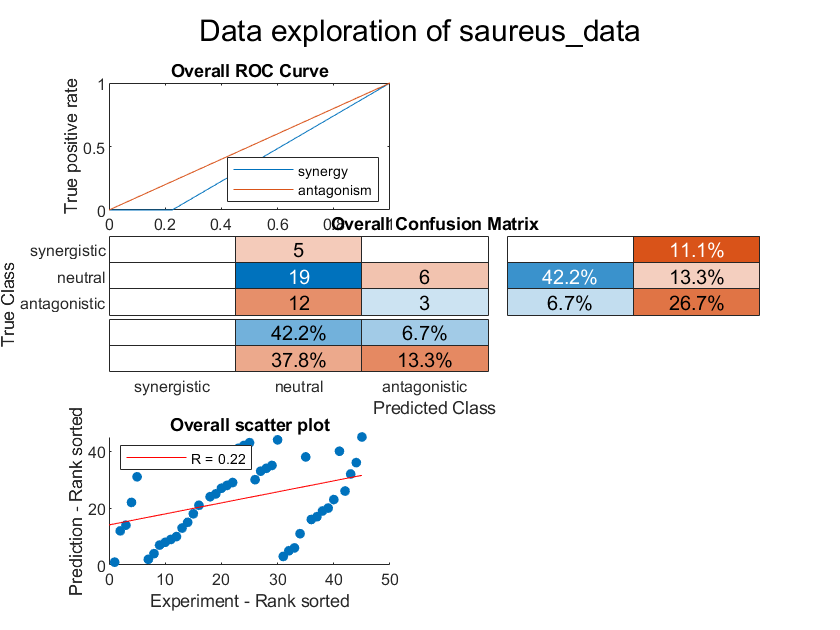

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9              0.25  

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.28333
    P value                     0.35861
    Accuracy                    0.48889
    Absolute error              0.51111
    Precision (synergy)             NaN
    Recall (synergy)                NaN
    Precision (antagonism)          0.4
    Recall (antagonism)         0.17333
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)             NaN
    AUC - ROC (antagonism)      0.49083


overviewTable = 12×1 table
                                 Value 
                                _______

    Interactions                     45
    R (rank)                    0.22196
    P value                     0.14281
    Accuracy                    0.48889
    Absolute error              0.51111
    Precision (synergy)             NaN
    Recall (synergy)                  0
    Precision (antagonism)      0.33333
    Recall (antagonism)             0.2
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)          0.3875
    AUC - ROC (antagonism)          0.5


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'saureus_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_staph_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 8.997471 seconds.
Run 2
Elapsed time is 8.173815 seconds.
Run 3
Elapsed time is 8.992382 seconds.
Run 4
Elapsed time is 8.132534 seconds.
Run 5
Elapsed time is 9.453397 seconds.


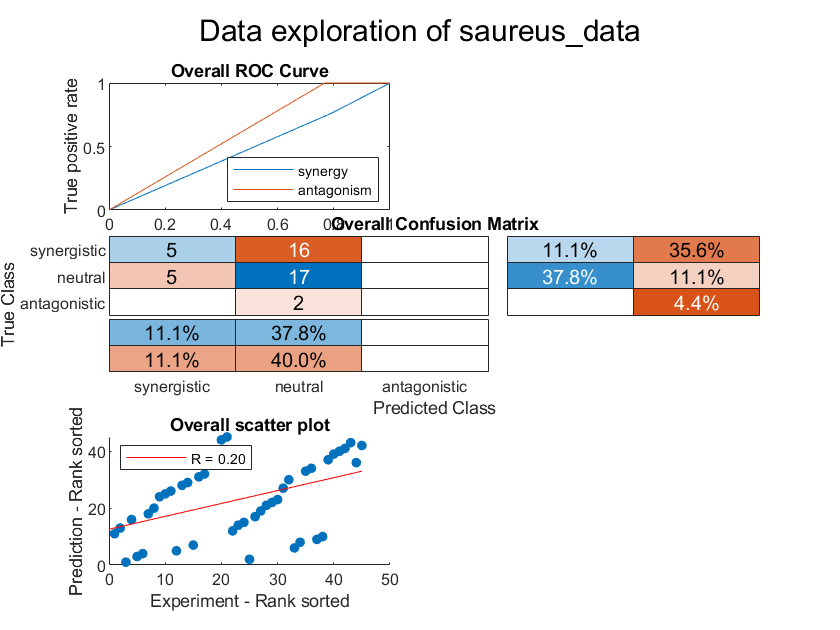

resultsTable = 5×12 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9            -0.15     0.

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.20667
    P value                     0.53711
    Accuracy                    0.48889
    Absolute error              0.51111
    Precision (synergy)             NaN
    Recall (synergy)            0.19667
    Precision (antagonism)          NaN
    Recall (antagonism)             NaN
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)            0.51
    AUC - ROC (antagonism)          NaN


overviewTable = 12×1 table
                                 Value 
                                _______

    Interactions                     45
    R (rank)                    0.19747
    P value                     0.19352
    Accuracy                    0.48889
    Absolute error              0.51111
    Precision (synergy)             0.5
    Recall (synergy)             0.2381
    Precision (antagonism)          NaN
    Recall (antagonism)               0
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.48512
    AUC - ROC (antagonism)      0.61628


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))